clear;
clc;
% add path where the data lives
prompt = {'Script User'};
answer = inputdlg(prompt);
addpath(genpath(cd));

%if they say nothing do nothing
if isempty(answer)
    return;
else

    user =  answer{1,1};
    [SubjectDirectory] = UserPath(user);
end

addpath(genpath(SubjectDirectory));


% load in the participant assignment table, with all the subject info

ParticipantAssignment = readtable("ParticipantAssignmentsUAB_corr.csv");
ParticipantAssignmentUCR = readtable("ParticipantAssignmentsUCR_corr.csv");
ParticipantAssignmentNE = readtable("ParticipantAssignmentsNEU_corr.csv");
ParticipantAssignment = [ParticipantAssignment; ParticipantAssignmentUCR; ParticipantAssignmentNE];

% k is a counter, it counts. use this to loop through your table and add new
% rows
k = 1;

% make counters for each training type as well. this will increase with
% every instance of a person doing each training type

tt1count = 1;
tt2count = 1;
tt3count = 1;
tt4count = 1;

% make a blank table, where we'll save all the important variables. make a
% table for the entire group as well as groups separated by training type.
DataTableRSVP = [];
DataTableRSVPTT1 = {};
DataTableRSVPTT2 = {};
DataTableRSVPTT3 = {};
DataTableRSVPTT4 = {};

% loop through the
% participant column in the assignment table

for z = 5:size(ParticipantAssignment,1)
    subjectID = char(ParticipantAssignment.participant(z));

    % make sure the subject is downloaded to your computer, you won't have
    % everyone until we have finished everyone

    % make sure the subject folder exists for the current index (this
    % condition is only met for participant's that have been downloaded to
    % your local folder)

    if exist([SubjectDirectory subjectID]) == 7 && sum(subjectID == 'fb1004') ~= 6 && sum(subjectID == 'fb1005') ~= 6 && sum(subjectID == 'fb1007') ~= 6 && sum(subjectID == 'fb1008') ~= 6 && sum(subjectID == 'fb1009') ~= 6 && sum(subjectID == 'fb1013') ~= 6 && sum(subjectID == 'fb1015') ~= 6  && sum(subjectID == 'fb1024') ~= 6 && sum(subjectID == 'fb1025') ~= 6

        % find the path where the pre-assessment data lives
        directoryPathPre = fullfile([SubjectDirectory subjectID '/pre']);
        FileNameRSVPPre = dir(fullfile([directoryPathPre '\' subjectID 'RSVP*.mat']));
        FileNameRSVPPre = FileNameRSVPPre.name;
        load(FileNameRSVPPre);

        congone=setdiff(onef,ddd(1,:));
        congtwo=setdiff(twof,ddd(2,:));
        congthree=setdiff(threef,ddd(3,:));
        congfour=setdiff(fourf,ddd(4,:));
        congfive=setdiff(fivef,ddd(5,:));
        congsix=setdiff(sixf,ddd(6,:));
        incongone=ddd(1,:);
        incongtwo=ddd(2,:);
        incongthree=ddd(3,:);
        incongfour=ddd(4,:);
        incongfive=ddd(5,:);
        incongsix=ddd(6,:); % note there is no 6th row in ddd

        % we need to add a +1 because the effect of the switch will be observed in
        % the following trial (each trial has a 'current location index' in
        % mixtr(trial,1) and a 'cued location index' in mixtr(trial, 2). Thus, the
        % effect of the cue is on the following trial

        targetarray=nan(length(mixtr),10);
        % for ui=6
        %     1: time
        %     2: button pressed (if third column is 0) OR stimulus identity (if
        %     third column is 1)
        %     3: timing identifier (0 = button press; 1 = timing stimulus)
        %     4: stim type (1-4: stimulus ori, 5 blank, 6 cue)

        for ui=1:length(respTime)
            mixtr(ui,:);

            respTimeT=respTime(ui,1:totalresptrial(ui));  % RT of key press (responses)

            respKeysT=respKeys(ui,1:totalresptrial(ui));    % keys pressed by participant

            % RT, key pressed, identify (0)= response item
            respmat=[respTimeT' respKeysT' zeros(length(respTimeT),2)];

            % stimluis identity
            theans(ui,:)'; % % stimluis identity
            %the ans
            %1-4: TRUE ANSWER TO DIRECTION OF TARGET
            %5: blank
            %6: cue
            %7: foil
            %8:post cue blank

            % timing of events:
            % 1:stim_start
            % 2: the ans (1-4: target ori, 5: foil, 6: cue, 7: blank, 8: post cue
            % blank)
            %3: identifier or stimulus item
            %4: stimulus identity (4: cue, 6: post cue interval)

            %stim type
            %1: target stays on screen until response
            %2: foil
            %3: target
            %4: cue
            %5 blank
            %6: post cue blank

            %stim_start: timing of the events
            % the ans: identity of the event

            eventmat=[stim_start(ui,1:length(trialArray{ui}))' theans(ui,1:length(trialArray{ui}))' ones(length(stim_start(ui,1:length(trialArray{ui}))),1) trialArray{ui}'];
            % time of stimulus - true answer- 1=event- trial array
            stimulimat=eventmat(eventmat(:,2)<5,:);


            The_event_mat{ui}=eventmat;
            %eventmat = [time - answer (type of response ) - event(1) or resp (0) - stimulus type]
            matt=[ eventmat; respmat];
            matt2=sortrows(matt); %sort rows by time of start of stimulus

            for i=2:length(matt2)
                matt2(i,1)=(matt2(i,1)-matt2(1,1));
            end
            matt2(1,1)=0;
            trialMax{ui}=matt2;
            % 1st Col = Start of Stimulus
            % 2nd Col= Type of Stimuli (1-4= orientation of target; 2=foil;
            % 5=blank)
            % 3rd Col= ones or zeros (event or response)
            % 4th Col= trial array= 3(target) 2(foil) 5(blank)
            clear matt matt2
            respFirstTarget= trialMax{ui}(trialMax{ui}(:,3)==0 & trialMax{ui}(:,1)<0.95 & trialMax{ui}(:,1)>0,:);
            % col 3=0 indicates that it is a response
            cheattrick{ui}= trialMax{ui}(trialMax{ui}(:,3)==0 & trialMax{ui}(:,1)== 0, :);

            % find RT response to the first target (switch target)
            if isempty(respFirstTarget)==0
                respFirstTargetRT(ui)=respFirstTarget(1);

                % if the response is below 50ms, try next one
                if respFirstTargetRT(ui)<0.08
                    respFirstTargetRT(ui)=respFirstTarget(2);
                end

                pointerResp(ui)=find(trialMax{ui}(:,1)==respFirstTargetRT(ui));
                % find the row where the RT is equal to the respFirstTarget ( need
                % to determine if the participant gave correct answer)

                %check if the response is correct
                corrresp(ui)=trialMax{ui}(pointerResp(ui),2)==trialMax{ui}(1,2);
                % if the ans = trialMax (actual response given by participant) then
                % response is CORRECT

            else
                respFirstTargetRT(ui)=NaN;
            end
            TotalResp(ui)= length(respKeysT);
            TotalTarget(ui)=sum(trialArray{ui}==3,"omitnan")-1; % 3= target
            respratio(ui)=TotalResp(ui)/TotalTarget(ui); %response ratio of participant (out of how many targets did participant actually respond)

            % resp accuracy + RT
            foun=find(trialArray{ui}==3);
            targetarray(ui,1:length(foun))=foun;
            newtargetarray(ui,1:length(foun)-1)=targetarray(ui,targetarray(ui,:)>1);

            %look for events around target presentation
            for i=1:TotalTarget(ui)
                %time stamp of the target
                timestamptarget(i,:)=trialMax{ui}(newtargetarray(ui,i),:);
                % candidate responses (events 'response' that took place after
                % target presentation)
                sustained_resp{ui,i}=trialMax{ui}(trialMax{ui}(:,1)>timestamptarget(i,1) & trialMax{ui}(:,3)==0, :);
            end
        end
        if length(respFirstTargetRT)<length(mixtr)
            diffrnc=length(mixtr)-length(respFirstTargetRT);
            respFirstTargetRT(length(respFirstTargetRT)+1:length(respFirstTargetRT)+diffrnc)=nan;
        end

        corrresp = double(corrresp);

        if length(corrresp)<length(mixtr)
            diffrnc=length(mixtr)-length(corrresp);
            corrresp(length(corrresp):length(corrresp)+diffrnc)=nan;
        end
        analysisMat=[mixtr corrresp' respFirstTargetRT'];
        % 1 to 2
        corrcongruentone=sum(analysisMat(congone,4),"omitnan")/length(analysisMat(congone,:));
        corrcongruentoneRT=mean(analysisMat(congone(analysisMat(congone,5)>0 & analysisMat(congone,4)>0),end),"omitnan");
        % 1 to 3
        corrcongruenttwo=sum(analysisMat(congtwo,4),"omitnan")/length(analysisMat(congtwo,:));
        corrcongruenttwoRT=mean(analysisMat(congtwo(analysisMat(congtwo,5)>0 & analysisMat(congtwo,4)>0),end),"omitnan");
        % 2 to 1
        corrcongruentthree=sum(analysisMat(congthree,4),"omitnan")/length(analysisMat(congthree,:));
        corrcongruentthreeRT=mean(analysisMat(congthree(analysisMat(congthree,5)>0 & analysisMat(congthree,4)>0),end),"omitnan");
        % 2 to 3
        corrcongruentfour=sum(analysisMat(congfour,4),"omitnan")/length(analysisMat(congfour,:));
        corrcongruentfourRT=mean(analysisMat(congfour(analysisMat(congfour,5)>0 & analysisMat(congfour,4)>0),end),"omitnan");
        % 3 to 1
        corrcongruentfive=sum(analysisMat(congfive,4),"omitnan")/length(analysisMat(congfive,:));
        corrcongruentfiveRT=mean(analysisMat(congfive(analysisMat(congfive,5)>0 & analysisMat(congfive,4)>0),end),"omitnan");
        % 3 to 2
        corrcongruentsix=sum(analysisMat(congsix,4),"omitnan")/length(analysisMat(congsix,:));
        corrcongruentsixRT=mean(analysisMat(congsix(analysisMat(congsix,5)>0 & analysisMat(congsix,4)>0),end),"omitnan");


        % incongruent trials

        % 1 to 2 the stream is on 1, the target goes to 2 but the cue is on 3)
        corrincongruentone=sum(analysisMat(incongone,4),"omitnan")/length(analysisMat(incongone,:));
        corrincongruentoneRT=mean(analysisMat(incongone(analysisMat(incongone,5)>0 & analysisMat(incongone,4)>0),end),"omitnan");
        % 1 to 3 the stream is on 1, the target goes to 3 but the cue is on 2)
        corrincongruenttwo=sum(analysisMat(incongtwo,4),"omitnan")/length(analysisMat(incongtwo,:));
        corrincongruenttwoRT=mean(analysisMat(incongtwo(analysisMat(incongtwo,5)>0 & analysisMat(incongtwo,4)>0),end),"omitnan");
        % 2 to 1 (the stream is on 2, the target goes to 1 but the cue is on 3)
        corrincongruentthree=sum(analysisMat(incongthree,4),"omitnan")/length(analysisMat(incongthree,:));
        corrincongruentthreeRT=mean(analysisMat(incongthree(analysisMat(incongthree,5)>0 & analysisMat(incongthree,4)>0),end),"omitnan");
        % 2 to 3
        corrincongruentfour=sum(analysisMat(incongfour,4),"omitnan")/length(analysisMat(incongfour,:));
        corrincongruentfourRT=mean(analysisMat(incongfour(analysisMat(incongfour,5)>0 & analysisMat(incongfour,4)>0),end),"omitnan");
        % 3 to 1
        corrincongruentfive=sum(analysisMat(incongfive,4),"omitnan")/length(analysisMat(incongfive,:));
        corrincongruentfiveRT=mean(analysisMat(incongfive(analysisMat(incongfive,5)>0 & analysisMat(incongfive,4)>0),end),"omitnan");
        % 3 to 2
        corrincongruentsix=sum(analysisMat(incongsix,4),"omitnan")/length(analysisMat(incongsix,:));
        corrincongruentsixRT=mean(analysisMat(incongsix(analysisMat(incongsix,5)>0 & analysisMat(incongsix,4)>0),end),"omitnan");

        


        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'L'
            TRL_to_URL_ConPC = corrcongruentone;
            URL_to_TRL_ConPC = corrcongruentthree;
            TRL_to_CRL_ConPC = corrcongruenttwo;
            URL_to_CRL_ConPC = corrcongruentfour;
            CRL_to_TRL_ConPC = corrcongruentfive;
            CRL_to_URL_ConPC = corrcongruentsix;

            TRL_to_URL_ConRT = corrcongruentoneRT;
            URL_to_TRL_ConRT = corrcongruentthreeRT;
            TRL_to_CRL_ConRT = corrcongruenttwoRT;
            URL_to_CRL_ConRT = corrcongruentfourRT;
            CRL_to_TRL_ConRT = corrcongruentfiveRT;
            CRL_to_URL_ConRT = corrcongruentsixRT;

            TRL_to_URL_InConPC = corrincongruentone;
            URL_to_TRL_InConPC = corrincongruentthree;
            TRL_to_CRL_InConPC = corrincongruenttwo;
            URL_to_CRL_InConPC = corrincongruentfour;
            CRL_to_TRL_InConPC = corrincongruentfive;
            CRL_to_URL_InConPC = corrincongruentsix;

            TRL_to_URL_InConRT = corrincongruentoneRT;
            URL_to_TRL_InConRT = corrincongruentthreeRT;
            TRL_to_CRL_InConRT = corrincongruenttwoRT;
            URL_to_CRL_InConRT = corrincongruentfourRT;
            CRL_to_TRL_InConRT = corrincongruentfiveRT;
            CRL_to_URL_InConRT = corrincongruentsixRT;

            TRL_to_URL_ConDiffPC = corrcongruentone - corrincongruentone;
            URL_to_TRL_ConDiffPC = corrcongruentthree - corrincongruentthree;
            TRL_to_CRL_ConDiffPC = corrcongruenttwo - corrincongruenttwo;
            URL_to_CRL_ConDiffPC = corrcongruentfour - corrincongruentfour;
            CRL_to_TRL_ConDiffPC = corrcongruentfive - corrincongruentfive;
            CRL_to_URL_ConDiffPC = corrcongruentsix - corrincongruentsix;

            TRL_to_URL_ConDiffRT = corrcongruentoneRT - corrincongruentoneRT;
            URL_to_TRL_ConDiffRT = corrcongruentthreeRT - corrincongruentthreeRT;
            TRL_to_CRL_ConDiffRT = corrcongruenttwoRT - corrincongruenttwoRT;
            URL_to_CRL_ConDiffRT = corrcongruentfourRT - corrincongruentfourRT;
            CRL_to_TRL_ConDiffRT = corrcongruentfiveRT - corrincongruentfiveRT;
            CRL_to_URL_ConDiffRT = corrcongruentsixRT - corrincongruentsixRT;

        elseif TrainedSide == 'R'
            TRL_to_URL_ConPC = corrcongruentthree;
            URL_to_TRL_ConPC = corrcongruentone;
            TRL_to_CRL_ConPC = corrcongruentfour;
            URL_to_CRL_ConPC = corrcongruenttwo;
            CRL_to_TRL_ConPC = corrcongruentsix;
            CRL_to_URL_ConPC = corrcongruentfive;

            TRL_to_URL_ConRT = corrcongruentthreeRT;
            URL_to_TRL_ConRT = corrcongruentoneRT;
            TRL_to_CRL_ConRT = corrcongruentfourRT;
            URL_to_CRL_ConRT = corrcongruenttwoRT;
            CRL_to_TRL_ConRT = corrcongruentsixRT;
            CRL_to_URL_ConRT = corrcongruentfiveRT;

            TRL_to_URL_InConPC = corrincongruentthree;
            URL_to_TRL_InConPC = corrincongruentone;
            TRL_to_CRL_InConPC = corrincongruentfour;
            URL_to_CRL_InConPC = corrincongruenttwo;
            CRL_to_TRL_InConPC = corrincongruentsix;
            CRL_to_URL_InConPC = corrincongruentfive;

            TRL_to_URL_InConRT = corrincongruentthreeRT;
            URL_to_TRL_InConRT = corrincongruentoneRT;
            TRL_to_CRL_InConRT = corrincongruentfourRT;
            URL_to_CRL_InConRT = corrincongruenttwoRT;
            CRL_to_TRL_InConRT = corrincongruentsixRT;
            CRL_to_URL_InConRT = corrincongruentfiveRT;

            TRL_to_URL_ConDiffPC = corrcongruentthree - corrincongruentthree;
            URL_to_TRL_ConDiffPC = corrcongruentone - corrincongruentone;
            TRL_to_CRL_ConDiffPC = corrcongruentfour - corrincongruentfour;
            URL_to_CRL_ConDiffPC = corrcongruenttwo - corrincongruentfour;
            CRL_to_TRL_ConDiffPC = corrcongruentsix - corrincongruentsix;
            CRL_to_URL_ConDiffPC = corrcongruentfive - corrincongruentfive;

            TRL_to_URL_ConDiffRT = corrcongruentthreeRT - corrincongruentthreeRT;
            URL_to_TRL_ConDiffRT = corrcongruentoneRT - corrincongruentoneRT;
            TRL_to_CRL_ConDiffRT = corrcongruentfourRT - corrincongruentfourRT;
            URL_to_CRL_ConDiffRT = corrcongruenttwoRT - corrincongruenttwoRT;
            CRL_to_TRL_ConDiffRT = corrcongruentsixRT - corrincongruentsixRT;
            CRL_to_URL_ConDiffRT = corrcongruentfiveRT - corrincongruentfiveRT;
        else
        end

        % Use the participant assignment table to find out the current
        % participant's trained side. use that info to send the data at each side
        % to the "trained" or "untrained" column later on


        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            DataTableRSVPTT1{tt1count,1} = subjectID;
            DataTableRSVPTT1{tt1count,2} = TRL_to_URL_ConPC;
            DataTableRSVPTT1{tt1count,3} = URL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,4} = TRL_to_CRL_ConPC;
            DataTableRSVPTT1{tt1count,5} = URL_to_CRL_ConPC;
            DataTableRSVPTT1{tt1count,6} = URL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,7} = CRL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,8} = CRL_to_URL_ConPC;
            DataTableRSVPTT1{tt1count,9} = TRL_to_URL_ConRT;
            DataTableRSVPTT1{tt1count,10} = URL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,11} = TRL_to_CRL_ConRT;
            DataTableRSVPTT1{tt1count,12} = URL_to_CRL_ConRT;
            DataTableRSVPTT1{tt1count,13} = URL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,14} = CRL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,15} = CRL_to_URL_ConRT;
            DataTableRSVPTT1{tt1count,16} = TRL_to_URL_InConPC;
            DataTableRSVPTT1{tt1count,17} = URL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,18} = TRL_to_CRL_InConPC;
            DataTableRSVPTT1{tt1count,19} = URL_to_CRL_InConPC;
            DataTableRSVPTT1{tt1count,20} = URL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,21} = CRL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,22} = CRL_to_URL_InConPC;
            DataTableRSVPTT1{tt1count,23} = TRL_to_URL_InConRT;
            DataTableRSVPTT1{tt1count,24} = URL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,25} = TRL_to_CRL_InConRT;
            DataTableRSVPTT1{tt1count,26} = URL_to_CRL_InConRT;
            DataTableRSVPTT1{tt1count,27} = URL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,28} = CRL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,29} = CRL_to_URL_InConRT;
            DataTableRSVPTT1{tt1count,30} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT1{tt1count,31} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,32} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,33} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,34} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,35} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,36} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT1{tt1count,37} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT1{tt1count,38} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,39} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,40} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,41} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,42} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,43} = CRL_to_URL_ConDiffRT;
            


        elseif TrainingType == '2'
            DataTableRSVPTT2{tt2count,1} = subjectID;
            DataTableRSVPTT2{tt2count,2} = TRL_to_URL_ConPC;
            DataTableRSVPTT2{tt2count,3} = URL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,4} = TRL_to_CRL_ConPC;
            DataTableRSVPTT2{tt2count,5} = URL_to_CRL_ConPC;
            DataTableRSVPTT2{tt2count,6} = URL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,7} = CRL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,8} = CRL_to_URL_ConPC;
            DataTableRSVPTT2{tt2count,9} = TRL_to_URL_ConRT;
            DataTableRSVPTT2{tt2count,10} = URL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,11} = TRL_to_CRL_ConRT;
            DataTableRSVPTT2{tt2count,12} = URL_to_CRL_ConRT;
            DataTableRSVPTT2{tt2count,13} = URL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,14} = CRL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,15} = CRL_to_URL_ConRT;
            DataTableRSVPTT2{tt2count,16} = TRL_to_URL_InConPC;
            DataTableRSVPTT2{tt2count,17} = URL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,18} = TRL_to_CRL_InConPC;
            DataTableRSVPTT2{tt2count,19} = URL_to_CRL_InConPC;
            DataTableRSVPTT2{tt2count,20} = URL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,21} = CRL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,22} = CRL_to_URL_InConPC;
            DataTableRSVPTT2{tt2count,23} = TRL_to_URL_InConRT;
            DataTableRSVPTT2{tt2count,24} = URL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,25} = TRL_to_CRL_InConRT;
            DataTableRSVPTT2{tt2count,26} = URL_to_CRL_InConRT;
            DataTableRSVPTT2{tt2count,27} = URL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,28} = CRL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,29} = CRL_to_URL_InConRT;
            DataTableRSVPTT2{tt2count,30} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT2{tt2count,31} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,32} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,33} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,34} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,35} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,36} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT2{tt2count,37} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT2{tt2count,38} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,39} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,40} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,41} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,42} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,43} = CRL_to_URL_ConDiffRT;
           

        elseif TrainingType == '3'
            DataTableRSVPTT3{tt3count,1} = subjectID;
            DataTableRSVPTT3{tt3count,2} = TRL_to_URL_ConPC;
            DataTableRSVPTT3{tt3count,3} = URL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,4} = TRL_to_CRL_ConPC;
            DataTableRSVPTT3{tt3count,5} = URL_to_CRL_ConPC;
            DataTableRSVPTT3{tt3count,6} = URL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,7} = CRL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,8} = CRL_to_URL_ConPC;
            DataTableRSVPTT3{tt3count,9} = TRL_to_URL_ConRT;
            DataTableRSVPTT3{tt3count,10} = URL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,11} = TRL_to_CRL_ConRT;
            DataTableRSVPTT3{tt3count,12} = URL_to_CRL_ConRT;
            DataTableRSVPTT3{tt3count,13} = URL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,14} = CRL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,15} = CRL_to_URL_ConRT;
            DataTableRSVPTT3{tt3count,16} = TRL_to_URL_InConPC;
            DataTableRSVPTT3{tt3count,17} = URL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,18} = TRL_to_CRL_InConPC;
            DataTableRSVPTT3{tt3count,19} = URL_to_CRL_InConPC;
            DataTableRSVPTT3{tt3count,20} = URL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,21} = CRL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,22} = CRL_to_URL_InConPC;
            DataTableRSVPTT3{tt3count,23} = TRL_to_URL_InConRT;
            DataTableRSVPTT3{tt3count,24} = URL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,25} = TRL_to_CRL_InConRT;
            DataTableRSVPTT3{tt3count,26} = URL_to_CRL_InConRT;
            DataTableRSVPTT3{tt3count,27} = URL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,28} = CRL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,29} = CRL_to_URL_InConRT;
            DataTableRSVPTT3{tt3count,30} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT3{tt3count,31} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,32} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,33} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,34} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,35} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,36} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT3{tt3count,37} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT3{tt3count,38} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,39} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,40} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,41} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,42} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,43} = CRL_to_URL_ConDiffRT;
            

        elseif TrainingType == '4'

            DataTableRSVPTT4{tt4count,1} = subjectID;
            DataTableRSVPTT4{tt4count,2} = TRL_to_URL_ConPC;
            DataTableRSVPTT4{tt4count,3} = URL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,4} = TRL_to_CRL_ConPC;
            DataTableRSVPTT4{tt4count,5} = URL_to_CRL_ConPC;
            DataTableRSVPTT4{tt4count,6} = URL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,7} = CRL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,8} = CRL_to_URL_ConPC;
            DataTableRSVPTT4{tt4count,9} = TRL_to_URL_ConRT;
            DataTableRSVPTT4{tt4count,10} = URL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,11} = TRL_to_CRL_ConRT;
            DataTableRSVPTT4{tt4count,12} = URL_to_CRL_ConRT;
            DataTableRSVPTT4{tt4count,13} = URL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,14} = CRL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,15} = CRL_to_URL_ConRT;
            DataTableRSVPTT4{tt4count,16} = TRL_to_URL_InConPC;
            DataTableRSVPTT4{tt4count,17} = URL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,18} = TRL_to_CRL_InConPC;
            DataTableRSVPTT4{tt4count,19} = URL_to_CRL_InConPC;
            DataTableRSVPTT4{tt4count,20} = URL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,21} = CRL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,22} = CRL_to_URL_InConPC;
            DataTableRSVPTT4{tt4count,23} = TRL_to_URL_InConRT;
            DataTableRSVPTT4{tt4count,24} = URL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,25} = TRL_to_CRL_InConRT;
            DataTableRSVPTT4{tt4count,26} = URL_to_CRL_InConRT;
            DataTableRSVPTT4{tt4count,27} = URL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,28} = CRL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,29} = CRL_to_URL_InConRT;
            DataTableRSVPTT4{tt4count,30} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT4{tt4count,31} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,32} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,33} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,34} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,35} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,36} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT4{tt4count,37} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT4{tt4count,38} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,39} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,40} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,41} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,42} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,43} = CRL_to_URL_ConDiffRT;
            

        else
        end




        clearvars -except  SubjectDirectory DataTableRSVP DataTableRSVPTT1 DataTableRSVPTT2 DataTableRSVPTT3 DataTableRSVPTT4 ParticipantAssignment k z tt1count tt2count tt3count tt4count subjectID


Post

        directoryPathPost = [SubjectDirectory subjectID '/post'];
        FileNameRSVPPost = dir([directoryPathPost '/' subjectID 'RSVP*.mat']);
        FileNameRSVPPost = FileNameRSVPPost.name;

        load(FileNameRSVPPost);

        congone=setdiff(onef,ddd(1,:));
        congtwo=setdiff(twof,ddd(2,:));
        congthree=setdiff(threef,ddd(3,:));
        congfour=setdiff(fourf,ddd(4,:));
        congfive=setdiff(fivef,ddd(5,:));
        congsix=setdiff(sixf,ddd(6,:));
        incongone=ddd(1,:);
        incongtwo=ddd(2,:);
        incongthree=ddd(3,:);
        incongfour=ddd(4,:);
        incongfive=ddd(5,:);
        incongsix=ddd(6,:); % note there is no 6th row in ddd

        % we need to add a +1 because the effect of the switch will be observed in
        % the following trial (each trial has a 'current location index' in
        % mixtr(trial,1) and a 'cued location index' in mixtr(trial, 2). Thus, the
        % effect of the cue is on the following trial

        targetarray=nan(length(mixtr),10);
        % for ui=6
        %     1: time
        %     2: button pressed (if third column is 0) OR stimulus identity (if
        %     third column is 1)
        %     3: timing identifier (0 = button press; 1 = timing stimulus)
        %     4: stim type (1-4: stimulus ori, 5 blank, 6 cue)

        for ui=1:length(respTime)
            mixtr(ui,:);

            respTimeT=respTime(ui,1:totalresptrial(ui));  % RT of key press (responses)

            respKeysT=respKeys(ui,1:totalresptrial(ui));    % keys pressed by participant

            % RT, key pressed, identify (0)= response item
            respmat=[respTimeT' respKeysT' zeros(length(respTimeT),2)];

            % stimluis identity
            theans(ui,:)'; % % stimluis identity
            %the ans
            %1-4: TRUE ANSWER TO DIRECTION OF TARGET
            %5: blank
            %6: cue
            %7: foil
            %8:post cue blank

            % timing of events:
            % 1:stim_start
            % 2: the ans (1-4: target ori, 5: foil, 6: cue, 7: blank, 8: post cue
            % blank)
            %3: identifier or stimulus item
            %4: stimulus identity (4: cue, 6: post cue interval)

            %stim type
            %1: target stays on screen until response
            %2: foil
            %3: target
            %4: cue
            %5 blank
            %6: post cue blank

            %stim_start: timing of the events
            % the ans: identity of the event

            eventmat=[stim_start(ui,1:length(trialArray{ui}))' theans(ui,1:length(trialArray{ui}))' ones(length(stim_start(ui,1:length(trialArray{ui}))),1) trialArray{ui}'];
            % time of stimulus - true answer- 1=event- trial array
            stimulimat=eventmat(eventmat(:,2)<5,:);


            The_event_mat{ui}=eventmat;
            %eventmat = [time - answer (type of response ) - event(1) or resp (0) - stimulus type]
            matt=[ eventmat; respmat];
            matt2=sortrows(matt); %sort rows by time of start of stimulus

            for i=2:length(matt2)
                matt2(i,1)=(matt2(i,1)-matt2(1,1));
            end
            matt2(1,1)=0;
            trialMax{ui}=matt2;
            % 1st Col = Start of Stimulus
            % 2nd Col= Type of Stimuli (1-4= orientation of target; 2=foil;
            % 5=blank)
            % 3rd Col= ones or zeros (event or response)
            % 4th Col= trial array= 3(target) 2(foil) 5(blank)
            clear matt matt2
            respFirstTarget= trialMax{ui}(trialMax{ui}(:,3)==0 & trialMax{ui}(:,1)<0.95 & trialMax{ui}(:,1)>0,:);
            % col 3=0 indicates that it is a response
            cheattrick{ui}= trialMax{ui}(trialMax{ui}(:,3)==0 & trialMax{ui}(:,1)== 0, :);

            % find RT response to the first target (switch target)
            if isempty(respFirstTarget)==0
                respFirstTargetRT(ui)=respFirstTarget(1);

                % if the response is below 50ms, try next one
                if respFirstTargetRT(ui)<0.08
                    respFirstTargetRT(ui)=respFirstTarget(2);
                end

                pointerResp(ui)=find(trialMax{ui}(:,1)==respFirstTargetRT(ui));
                % find the row where the RT is equal to the respFirstTarget ( need
                % to determine if the participant gave correct answer)

                %check if the response is correct
                corrresp(ui)=trialMax{ui}(pointerResp(ui),2)==trialMax{ui}(1,2);
                % if the ans = trialMax (actual response given by participant) then
                % response is CORRECT

            else
                respFirstTargetRT(ui)=NaN;
            end
            TotalResp(ui)= length(respKeysT);
            TotalTarget(ui)=sum(trialArray{ui}==3,"omitnan")-1; % 3= target
            respratio(ui)=TotalResp(ui)/TotalTarget(ui); %response ratio of participant (out of how many targets did participant actually respond)

            % resp accuracy + RT
            foun=find(trialArray{ui}==3);
            targetarray(ui,1:length(foun))=foun;
            newtargetarray(ui,1:length(foun)-1)=targetarray(ui,targetarray(ui,:)>1);

            %look for events around target presentation
            for i=1:TotalTarget(ui)
                %time stamp of the target
                timestamptarget(i,:)=trialMax{ui}(newtargetarray(ui,i),:);
                % candidate responses (events 'response' that took place after
                % target presentation)
                sustained_resp{ui,i}=trialMax{ui}(trialMax{ui}(:,1)>timestamptarget(i,1) & trialMax{ui}(:,3)==0, :);
            end
        end
        if length(respFirstTargetRT)<length(mixtr)
            diffrnc=length(mixtr)-length(respFirstTargetRT);
            respFirstTargetRT(length(respFirstTargetRT)+1:length(respFirstTargetRT)+diffrnc)=nan;
        end

        corrresp = double(corrresp);

        if length(corrresp)<length(mixtr)
            diffrnc=length(mixtr)-length(corrresp);
            corrresp(length(corrresp):length(corrresp)+diffrnc)=nan;
        end
        analysisMat=[mixtr corrresp' respFirstTargetRT'];
        % 1 to 2
        corrcongruentone=sum(analysisMat(congone,4),"omitnan")/length(analysisMat(congone,:));
        corrcongruentoneRT=mean(analysisMat(congone(analysisMat(congone,5)>0 & analysisMat(congone,4)>0),end),"omitnan");
        % 1 to 3
        corrcongruenttwo=sum(analysisMat(congtwo,4),"omitnan")/length(analysisMat(congtwo,:));
        corrcongruenttwoRT=mean(analysisMat(congtwo(analysisMat(congtwo,5)>0 & analysisMat(congtwo,4)>0),end),"omitnan");
        % 2 to 1
        corrcongruentthree=sum(analysisMat(congthree,4),"omitnan")/length(analysisMat(congthree,:));
        corrcongruentthreeRT=mean(analysisMat(congthree(analysisMat(congthree,5)>0 & analysisMat(congthree,4)>0),end),"omitnan");
        % 2 to 3
        corrcongruentfour=sum(analysisMat(congfour,4),"omitnan")/length(analysisMat(congfour,:));
        corrcongruentfourRT=mean(analysisMat(congfour(analysisMat(congfour,5)>0 & analysisMat(congfour,4)>0),end),"omitnan");
        % 3 to 1
        corrcongruentfive=sum(analysisMat(congfive,4),"omitnan")/length(analysisMat(congfive,:));
        corrcongruentfiveRT=mean(analysisMat(congfive(analysisMat(congfive,5)>0 & analysisMat(congfive,4)>0),end),"omitnan");
        % 3 to 2
        corrcongruentsix=sum(analysisMat(congsix,4),"omitnan")/length(analysisMat(congsix,:));
        corrcongruentsixRT=mean(analysisMat(congsix(analysisMat(congsix,5)>0 & analysisMat(congsix,4)>0),end),"omitnan");


        % incongruent trials

        % 1 to 2 the stream is on 1, the target goes to 2 but the cue is on 3)
        corrincongruentone=sum(analysisMat(incongone,4),"omitnan")/length(analysisMat(incongone,:));
        corrincongruentoneRT=mean(analysisMat(incongone(analysisMat(incongone,5)>0 & analysisMat(incongone,4)>0),end),"omitnan");
        % 1 to 3 the stream is on 1, the target goes to 3 but the cue is on 2)
        corrincongruenttwo=sum(analysisMat(incongtwo,4),"omitnan")/length(analysisMat(incongtwo,:));
        corrincongruenttwoRT=mean(analysisMat(incongtwo(analysisMat(incongtwo,5)>0 & analysisMat(incongtwo,4)>0),end),"omitnan");
        % 2 to 1 (the stream is on 2, the target goes to 1 but the cue is on 3)
        corrincongruentthree=sum(analysisMat(incongthree,4),"omitnan")/length(analysisMat(incongthree,:));
        corrincongruentthreeRT=mean(analysisMat(incongthree(analysisMat(incongthree,5)>0 & analysisMat(incongthree,4)>0),end),"omitnan");
        % 2 to 3
        corrincongruentfour=sum(analysisMat(incongfour,4),"omitnan")/length(analysisMat(incongfour,:));
        corrincongruentfourRT=mean(analysisMat(incongfour(analysisMat(incongfour,5)>0 & analysisMat(incongfour,4)>0),end),"omitnan");
        % 3 to 1
        corrincongruentfive=sum(analysisMat(incongfive,4),"omitnan")/length(analysisMat(incongfive,:));
        corrincongruentfiveRT=mean(analysisMat(incongfive(analysisMat(incongfive,5)>0 & analysisMat(incongfive,4)>0),end),"omitnan");
        % 3 to 2
        corrincongruentsix=sum(analysisMat(incongsix,4),"omitnan")/length(analysisMat(incongsix,:));
        corrincongruentsixRT=mean(analysisMat(incongsix(analysisMat(incongsix,5)>0 & analysisMat(incongsix,4)>0),end),"omitnan");

       


        TrainedSide = char(ParticipantAssignment.TRL(z));
        if TrainedSide == 'L'
            TRL_to_URL_ConPC = corrcongruentone;
            URL_to_TRL_ConPC = corrcongruentthree;
            TRL_to_CRL_ConPC = corrcongruenttwo;
            URL_to_CRL_ConPC = corrcongruentfour;
            CRL_to_TRL_ConPC = corrcongruentfive;
            CRL_to_URL_ConPC = corrcongruentsix;

            TRL_to_URL_ConRT = corrcongruentoneRT;
            URL_to_TRL_ConRT = corrcongruentthreeRT;
            TRL_to_CRL_ConRT = corrcongruenttwoRT;
            URL_to_CRL_ConRT = corrcongruentfourRT;
            CRL_to_TRL_ConRT = corrcongruentfiveRT;
            CRL_to_URL_ConRT = corrcongruentsixRT;

            TRL_to_URL_InConPC = corrincongruentone;
            URL_to_TRL_InConPC = corrincongruentthree;
            TRL_to_CRL_InConPC = corrincongruenttwo;
            URL_to_CRL_InConPC = corrincongruentfour;
            CRL_to_TRL_InConPC = corrincongruentfive;
            CRL_to_URL_InConPC = corrincongruentsix;

            TRL_to_URL_InConRT = corrincongruentoneRT;
            URL_to_TRL_InConRT = corrincongruentthreeRT;
            TRL_to_CRL_InConRT = corrincongruenttwoRT;
            URL_to_CRL_InConRT = corrincongruentfourRT;
            CRL_to_TRL_InConRT = corrincongruentfiveRT;
            CRL_to_URL_InConRT = corrincongruentsixRT;

            TRL_to_URL_ConDiffPC = corrcongruentone - corrincongruentone;
            URL_to_TRL_ConDiffPC = corrcongruentthree - corrincongruentthree;
            TRL_to_CRL_ConDiffPC = corrcongruenttwo - corrincongruenttwo;
            URL_to_CRL_ConDiffPC = corrcongruentfour - corrincongruentfour;
            CRL_to_TRL_ConDiffPC = corrcongruentfive - corrincongruentfive;
            CRL_to_URL_ConDiffPC = corrcongruentsix - corrincongruentsix;

            TRL_to_URL_ConDiffRT = corrcongruentoneRT - corrincongruentoneRT;
            URL_to_TRL_ConDiffRT = corrcongruentthreeRT - corrincongruentthreeRT;
            TRL_to_CRL_ConDiffRT = corrcongruenttwoRT - corrincongruenttwoRT;
            URL_to_CRL_ConDiffRT = corrcongruentfourRT - corrincongruentfourRT;
            CRL_to_TRL_ConDiffRT = corrcongruentfiveRT - corrincongruentfiveRT;
            CRL_to_URL_ConDiffRT = corrcongruentsixRT - corrincongruentsixRT;

        elseif TrainedSide == 'R'
            TRL_to_URL_ConPC = corrcongruentthree;
            URL_to_TRL_ConPC = corrcongruentone;
            TRL_to_CRL_ConPC = corrcongruentfour;
            URL_to_CRL_ConPC = corrcongruenttwo;
            CRL_to_TRL_ConPC = corrcongruentsix;
            CRL_to_URL_ConPC = corrcongruentfive;

            TRL_to_URL_ConRT = corrcongruentthreeRT;
            URL_to_TRL_ConRT = corrcongruentoneRT;
            TRL_to_CRL_ConRT = corrcongruentfourRT;
            URL_to_CRL_ConRT = corrcongruenttwoRT;
            CRL_to_TRL_ConRT = corrcongruentsixRT;
            CRL_to_URL_ConRT = corrcongruentfiveRT;

            TRL_to_URL_InConPC = corrincongruentthree;
            URL_to_TRL_InConPC = corrincongruentone;
            TRL_to_CRL_InConPC = corrincongruentfour;
            URL_to_CRL_InConPC = corrincongruenttwo;
            CRL_to_TRL_InConPC = corrincongruentsix;
            CRL_to_URL_InConPC = corrincongruentfive;

            TRL_to_URL_InConRT = corrincongruentthreeRT;
            URL_to_TRL_InConRT = corrincongruentoneRT;
            TRL_to_CRL_InConRT = corrincongruentfourRT;
            URL_to_CRL_InConRT = corrincongruenttwoRT;
            CRL_to_TRL_InConRT = corrincongruentsixRT;
            CRL_to_URL_InConRT = corrincongruentfiveRT;

            TRL_to_URL_ConDiffPC = corrcongruentthree - corrincongruentthree;
            URL_to_TRL_ConDiffPC = corrcongruentone - corrincongruentone;
            TRL_to_CRL_ConDiffPC = corrcongruentfour - corrincongruentfour;
            URL_to_CRL_ConDiffPC = corrcongruenttwo - corrincongruentfour;
            CRL_to_TRL_ConDiffPC = corrcongruentsix - corrincongruentsix;
            CRL_to_URL_ConDiffPC = corrcongruentfive - corrincongruentfive;

            TRL_to_URL_ConDiffRT = corrcongruentthreeRT - corrincongruentthreeRT;
            URL_to_TRL_ConDiffRT = corrcongruentoneRT - corrincongruentoneRT;
            TRL_to_CRL_ConDiffRT = corrcongruentfourRT - corrincongruentfourRT;
            URL_to_CRL_ConDiffRT = corrcongruenttwoRT - corrincongruenttwoRT;
            CRL_to_TRL_ConDiffRT = corrcongruentsixRT - corrincongruentsixRT;
            CRL_to_URL_ConDiffRT = corrcongruentfiveRT - corrincongruentfiveRT;
        else
        end

        % Use the participant assignment table to find out the current
        % participant's trained side. use that info to send the data at each side
        % to the "trained" or "untrained" column later on


        TrainingType = string(double(ParticipantAssignment.TrainingTask(z)));
        if TrainingType == '1'
            DataTableRSVPTT1{tt1count,1} = subjectID;
            DataTableRSVPTT1{tt1count,44} = TRL_to_URL_ConPC;
            DataTableRSVPTT1{tt1count,45} = URL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,46} = TRL_to_CRL_ConPC;
            DataTableRSVPTT1{tt1count,47} = URL_to_CRL_ConPC;
            DataTableRSVPTT1{tt1count,48} = URL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,49} = CRL_to_TRL_ConPC;
            DataTableRSVPTT1{tt1count,50} = CRL_to_URL_ConPC;
            DataTableRSVPTT1{tt1count,51} = TRL_to_URL_ConRT;
            DataTableRSVPTT1{tt1count,52} = URL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,53} = TRL_to_CRL_ConRT;
            DataTableRSVPTT1{tt1count,54} = URL_to_CRL_ConRT;
            DataTableRSVPTT1{tt1count,55} = URL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,56} = CRL_to_TRL_ConRT;
            DataTableRSVPTT1{tt1count,57} = CRL_to_URL_ConRT;
            DataTableRSVPTT1{tt1count,58} = TRL_to_URL_InConPC;
            DataTableRSVPTT1{tt1count,59} = URL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,60} = TRL_to_CRL_InConPC;
            DataTableRSVPTT1{tt1count,61} = URL_to_CRL_InConPC;
            DataTableRSVPTT1{tt1count,62} = URL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,63} = CRL_to_TRL_InConPC;
            DataTableRSVPTT1{tt1count,64} = CRL_to_URL_InConPC;
            DataTableRSVPTT1{tt1count,65} = TRL_to_URL_InConRT;
            DataTableRSVPTT1{tt1count,66} = URL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,67} = TRL_to_CRL_InConRT;
            DataTableRSVPTT1{tt1count,68} = URL_to_CRL_InConRT;
            DataTableRSVPTT1{tt1count,69} = URL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,70} = CRL_to_TRL_InConRT;
            DataTableRSVPTT1{tt1count,71} = CRL_to_URL_InConRT;
            DataTableRSVPTT1{tt1count,72} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT1{tt1count,73} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,74} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,75} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,76} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,77} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT1{tt1count,78} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT1{tt1count,79} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT1{tt1count,80} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,81} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,82} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,83} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,84} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT1{tt1count,85} = CRL_to_URL_ConDiffRT;
            tt1count = tt1count + 1;


        elseif TrainingType == '2'
            DataTableRSVPTT2{tt2count,1} = subjectID;
            DataTableRSVPTT2{tt2count,44} = TRL_to_URL_ConPC;
            DataTableRSVPTT2{tt2count,45} = URL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,46} = TRL_to_CRL_ConPC;
            DataTableRSVPTT2{tt2count,47} = URL_to_CRL_ConPC;
            DataTableRSVPTT2{tt2count,48} = URL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,49} = CRL_to_TRL_ConPC;
            DataTableRSVPTT2{tt2count,50} = CRL_to_URL_ConPC;
            DataTableRSVPTT2{tt2count,51} = TRL_to_URL_ConRT;
            DataTableRSVPTT2{tt2count,52} = URL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,53} = TRL_to_CRL_ConRT;
            DataTableRSVPTT2{tt2count,54} = URL_to_CRL_ConRT;
            DataTableRSVPTT2{tt2count,55} = URL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,56} = CRL_to_TRL_ConRT;
            DataTableRSVPTT2{tt2count,57} = CRL_to_URL_ConRT;
            DataTableRSVPTT2{tt2count,58} = TRL_to_URL_InConPC;
            DataTableRSVPTT2{tt2count,59} = URL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,60} = TRL_to_CRL_InConPC;
            DataTableRSVPTT2{tt2count,61} = URL_to_CRL_InConPC;
            DataTableRSVPTT2{tt2count,62} = URL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,63} = CRL_to_TRL_InConPC;
            DataTableRSVPTT2{tt2count,64} = CRL_to_URL_InConPC;
            DataTableRSVPTT2{tt2count,65} = TRL_to_URL_InConRT;
            DataTableRSVPTT2{tt2count,66} = URL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,67} = TRL_to_CRL_InConRT;
            DataTableRSVPTT2{tt2count,68} = URL_to_CRL_InConRT;
            DataTableRSVPTT2{tt2count,69} = URL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,70} = CRL_to_TRL_InConRT;
            DataTableRSVPTT2{tt2count,71} = CRL_to_URL_InConRT;
            DataTableRSVPTT2{tt2count,72} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT2{tt2count,73} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,74} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,75} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,76} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,77} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT2{tt2count,78} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT2{tt2count,79} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT2{tt2count,80} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,81} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,82} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,83} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,84} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT2{tt2count,85} = CRL_to_URL_ConDiffRT;
             tt2count = tt2count + 1;

        elseif TrainingType == '3'
            DataTableRSVPTT3{tt3count,1} = subjectID;
            DataTableRSVPTT3{tt3count,44} = TRL_to_URL_ConPC;
            DataTableRSVPTT3{tt3count,45} = URL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,46} = TRL_to_CRL_ConPC;
            DataTableRSVPTT3{tt3count,47} = URL_to_CRL_ConPC;
            DataTableRSVPTT3{tt3count,48} = URL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,49} = CRL_to_TRL_ConPC;
            DataTableRSVPTT3{tt3count,50} = CRL_to_URL_ConPC;
            DataTableRSVPTT3{tt3count,51} = TRL_to_URL_ConRT;
            DataTableRSVPTT3{tt3count,52} = URL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,53} = TRL_to_CRL_ConRT;
            DataTableRSVPTT3{tt3count,54} = URL_to_CRL_ConRT;
            DataTableRSVPTT3{tt3count,55} = URL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,56} = CRL_to_TRL_ConRT;
            DataTableRSVPTT3{tt3count,57} = CRL_to_URL_ConRT;
            DataTableRSVPTT3{tt3count,58} = TRL_to_URL_InConPC;
            DataTableRSVPTT3{tt3count,59} = URL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,60} = TRL_to_CRL_InConPC;
            DataTableRSVPTT3{tt3count,61} = URL_to_CRL_InConPC;
            DataTableRSVPTT3{tt3count,62} = URL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,63} = CRL_to_TRL_InConPC;
            DataTableRSVPTT3{tt3count,64} = CRL_to_URL_InConPC;
            DataTableRSVPTT3{tt3count,65} = TRL_to_URL_InConRT;
            DataTableRSVPTT3{tt3count,66} = URL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,67} = TRL_to_CRL_InConRT;
            DataTableRSVPTT3{tt3count,68} = URL_to_CRL_InConRT;
            DataTableRSVPTT3{tt3count,69} = URL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,70} = CRL_to_TRL_InConRT;
            DataTableRSVPTT3{tt3count,71} = CRL_to_URL_InConRT;
            DataTableRSVPTT3{tt3count,72} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT3{tt3count,73} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,74} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,75} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,76} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,77} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT3{tt3count,78} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT3{tt3count,79} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT3{tt3count,80} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,81} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,82} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,83} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,84} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT3{tt3count,85} = CRL_to_URL_ConDiffRT;
            tt3count = tt3count + 1;

        elseif TrainingType == '4'

            DataTableRSVPTT4{tt4count,1} = subjectID;
            DataTableRSVPTT4{tt4count,44} = TRL_to_URL_ConPC;
            DataTableRSVPTT4{tt4count,45} = URL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,46} = TRL_to_CRL_ConPC;
            DataTableRSVPTT4{tt4count,47} = URL_to_CRL_ConPC;
            DataTableRSVPTT4{tt4count,48} = URL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,49} = CRL_to_TRL_ConPC;
            DataTableRSVPTT4{tt4count,50} = CRL_to_URL_ConPC;
            DataTableRSVPTT4{tt4count,51} = TRL_to_URL_ConRT;
            DataTableRSVPTT4{tt4count,52} = URL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,53} = TRL_to_CRL_ConRT;
            DataTableRSVPTT4{tt4count,54} = URL_to_CRL_ConRT;
            DataTableRSVPTT4{tt4count,55} = URL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,56} = CRL_to_TRL_ConRT;
            DataTableRSVPTT4{tt4count,57} = CRL_to_URL_ConRT;
            DataTableRSVPTT4{tt4count,58} = TRL_to_URL_InConPC;
            DataTableRSVPTT4{tt4count,59} = URL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,60} = TRL_to_CRL_InConPC;
            DataTableRSVPTT4{tt4count,61} = URL_to_CRL_InConPC;
            DataTableRSVPTT4{tt4count,62} = URL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,63} = CRL_to_TRL_InConPC;
            DataTableRSVPTT4{tt4count,64} = CRL_to_URL_InConPC;
            DataTableRSVPTT4{tt4count,65} = TRL_to_URL_InConRT;
            DataTableRSVPTT4{tt4count,66} = URL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,67} = TRL_to_CRL_InConRT;
            DataTableRSVPTT4{tt4count,68} = URL_to_CRL_InConRT;
            DataTableRSVPTT4{tt4count,69} = URL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,70} = CRL_to_TRL_InConRT;
            DataTableRSVPTT4{tt4count,71} = CRL_to_URL_InConRT;
            DataTableRSVPTT4{tt4count,72} = TRL_to_URL_ConDiffPC;
            DataTableRSVPTT4{tt4count,73} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,74} = TRL_to_CRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,75} = URL_to_CRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,76} = URL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,77} = CRL_to_TRL_ConDiffPC;
            DataTableRSVPTT4{tt4count,78} = CRL_to_URL_ConDiffPC;
            DataTableRSVPTT4{tt4count,79} = TRL_to_URL_ConDiffRT;
            DataTableRSVPTT4{tt4count,80} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,81} = TRL_to_CRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,82} = URL_to_CRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,83} = URL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,84} = CRL_to_TRL_ConDiffRT;
            DataTableRSVPTT4{tt4count,85} = CRL_to_URL_ConDiffRT;
            tt4count = tt4count + 1;

            clearvars -except  SubjectDirectory DataTableRSVP DataTableRSVPTT1 DataTableRSVPTT2 DataTableRSVPTT3 DataTableRSVPTT4 ParticipantAssignment k z tt1count tt2count tt3count tt4count subjectID
        else
        end
    else
    end
end


graphs

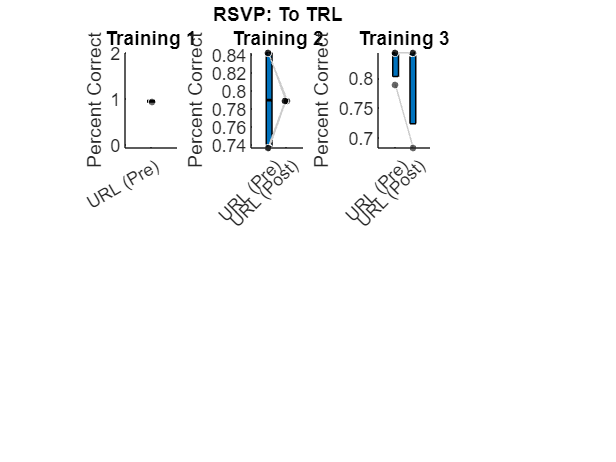

% create label names for each condition of data

condition_names = {'URL (Pre)', 'URL (Post)','CRL (Pre)', 'CRL (Post)', 'TRL (Pre)','TRL (Post)'};
f1 = figure;

%

% to TRL: make sub-arrays for conditions that go from another area to the
% TRL. so URL-TRL and CRL-TRL.

To_TRLPCTT1(:,1) = cell2mat({DataTableRSVPTT1{:,3}}); % URL to TRL con PC pre
To_TRLPCTT1(:,2) = cell2mat({DataTableRSVPTT1{:,45}}); % URL to TRL con PC post
To_TRLPCTT1(:,3) = cell2mat({DataTableRSVPTT1{:,7}}); % CRL to TRL con PC pre
To_TRLPCTT1(:,4) = cell2mat({DataTableRSVPTT1{:,49}}); % CRL to TRL con PC post


subplot(2, 4, 1)

j1 = daboxplot(To_TRLPCTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])


To_TRLPCTT2(:,1) = cell2mat({DataTableRSVPTT2{:,3}}); % URL to TRL con PC pre
To_TRLPCTT2(:,2) = cell2mat({DataTableRSVPTT2{:,45}}); % URL to TRL con PC post
To_TRLPCTT2(:,3) = cell2mat({DataTableRSVPTT2{:,7}}); % CRL to TRL con PC pre
To_TRLPCTT2(:,4) = cell2mat({DataTableRSVPTT2{:,49}}); % CRL to TRL con PC post


subplot(2, 4, 2)
j2 = daboxplot(To_TRLPCTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title(['RSVP: To TRL' newline 'Training 2'])

To_TRLPCTT3(:,1) = cell2mat({DataTableRSVPTT3{:,3}}); % URL to TRL con PC pre
To_TRLPCTT3(:,2) = cell2mat({DataTableRSVPTT3{:,45}}); % URL to TRL con PC post
To_TRLPCTT3(:,3) = cell2mat({DataTableRSVPTT3{:,7}}); % CRL to TRL con PC pre
To_TRLPCTT3(:,4) = cell2mat({DataTableRSVPTT3{:,49}}); % CRL to TRL con PC post

subplot(2, 4, 3)
j3 = daboxplot(To_TRLPCTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])


To_TRLPCTT4(:,1) = cell2mat({DataTableRSVPTT4{:,3}}); % URL to TRL con PC pre

Index in position 2 exceeds array bounds.

To_TRLPCTT4(:,2) = cell2mat({DataTableRSVPTT4{:,45}}); % URL to TRL con PC post
To_TRLPCTT4(:,3) = cell2mat({DataTableRSVPTT4{:,7}}); % CRL to TRL con PC pre
To_TRLPCTT4(:,4) = cell2mat({DataTableRSVPTT4{:,49}}); % CRL to TRL con PC post


subplot(2, 4, 4)
j4 = daboxplot(To_TRLPCTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_TRLPCTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_TRLPCTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_TRLPCTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_TRLPCTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])



figure;

% to URL: make sub-arrays for conditions that go from another area to the
% URL. so TRL-URL and CRL-URL.

To_URLPCTT1(:,1) = cell2mat({DataTableRSVPTT1{:,2}}); % TRL to URL con PC pre
To_URLPCTT1(:,2) = cell2mat({DataTableRSVPTT1{:,44}}); % TRL to URL con PC post
To_URLPCTT1(:,3) = cell2mat({DataTableRSVPTT1{:,8}}); % CRL to URL con PC pre
To_URLPCTT1(:,4) = cell2mat({DataTableRSVPTT1{:,50}}); % CRL to URL con PC post


subplot(2, 4, 1)

j1 = daboxplot(To_URLPCTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])


To_URLPCTT2(:,1) = cell2mat({DataTableRSVPTT2{:,2}}); % TRL to URL con PC pre
To_URLPCTT2(:,2) = cell2mat({DataTableRSVPTT2{:,44}}); % TRL to URL con PC post
To_URLPCTT2(:,3) = cell2mat({DataTableRSVPTT2{:,8}}); % CRL to URL con PC pre
To_URLPCTT2(:,4) = cell2mat({DataTableRSVPTT2{:,50}}); % CRL to URL con PC post


subplot(2, 4, 2)
j2 = daboxplot(To_URLPCTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title(['RSVP: To URL' newline 'Training 2'])

To_URLPCTT3(:,1) = cell2mat({DataTableRSVPTT3{:,2}}); % TRL to URL con PC pre
To_URLPCTT3(:,2) = cell2mat({DataTableRSVPTT3{:,44}}); % TRL to URL con PC post
To_URLPCTT3(:,3) = cell2mat({DataTableRSVPTT3{:,8}}); % CRL to URL con PC pre
To_URLPCTT3(:,4) = cell2mat({DataTableRSVPTT3{:,50}}); % CRL to URL con PC post

subplot(2, 4, 3)
j3 = daboxplot(To_URLPCTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])

To_URLPCTT4(:,1) = cell2mat({DataTableRSVPTT4{:,2}}); % TRL to URL con PC pre
To_URLPCTT4(:,2) = cell2mat({DataTableRSVPTT4{:,44}}); % TRL to URL con PC post
To_URLPCTT4(:,3) = cell2mat({DataTableRSVPTT4{:,8}}); % CRL to URL con PC pre
To_URLPCTT4(:,4) = cell2mat({DataTableRSVPTT4{:,50}}); % CRL to URL con PC post


subplot(2, 4, 4)
j4 = daboxplot(To_URLPCTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_URLPCTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_URLPCTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_URLPCTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_URLPCTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])

figure;

% to CRL: make sub-arrays for conditions that go from another area to the
% CRL. so TRL-CRL and CRL-CRL.

To_CRLPCTT1(:,1) = cell2mat({DataTableRSVPTT1{:,4}}); % TRL to CRL con PC pre
To_CRLPCTT1(:,2) = cell2mat({DataTableRSVPTT1{:,46}}); % TRL to CRL con PC post
To_CRLPCTT1(:,3) = cell2mat({DataTableRSVPTT1{:,5}}); % URL to CRL con PC pre
To_CRLPCTT1(:,4) = cell2mat({DataTableRSVPTT1{:,47}}); % URL to CRL con PC post


subplot(2, 4, 1)

j1 = daboxplot(To_CRLPCTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])


To_CRLPCTT2(:,1) = cell2mat({DataTableRSVPTT2{:,4}}); % TRL to CRL con PC pre
To_CRLPCTT2(:,2) = cell2mat({DataTableRSVPTT2{:,46}}); % TRL to CRL con PC post
To_CRLPCTT2(:,3) = cell2mat({DataTableRSVPTT2{:,5}}); % URL to CRL con PC pre
To_CRLPCTT2(:,4) = cell2mat({DataTableRSVPTT2{:,47}}); % URL to CRL con PC post


subplot(2, 4, 2)
j2 = daboxplot(To_CRLPCTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title(['RSVP: To CRL' newline 'Training 2'])

To_CRLPCTT3(:,1) = cell2mat({DataTableRSVPTT3{:,4}}); % TRL to CRL con PC pre
To_CRLPCTT3(:,2) = cell2mat({DataTableRSVPTT3{:,46}}); % TRL to CRL con PC post
To_CRLPCTT3(:,3) = cell2mat({DataTableRSVPTT3{:,5}}); % URL to CRL con PC pre
To_CRLPCTT3(:,4) = cell2mat({DataTableRSVPTT3{:,47}}); % URL to CRL con PC post

subplot(2, 4, 3)
j3 = daboxplot(To_CRLPCTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])

To_CRLPCTT4(:,1) = cell2mat({DataTableRSVPTT4{:,4}}); % TRL to CRL con PC pre
To_CRLPCTT4(:,2) = cell2mat({DataTableRSVPTT4{:,46}}); % TRL to CRL con PC post
To_CRLPCTT4(:,3) = cell2mat({DataTableRSVPTT4{:,5}}); % URL to CRL con PC pre
To_CRLPCTT4(:,4) = cell2mat({DataTableRSVPTT4{:,47}}); % URL to CRL con PC post


subplot(2, 4, 4)
j4 = daboxplot(To_CRLPCTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_CRLPCTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_CRLPCTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_CRLPCTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_CRLPCTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('Percent Correct')
title([newline 'Training 4'])






let's do it again for RT

% to TRL: make sub-arrays for conditions that go from another area to the
% TRL. so URL-TRL and CRL-TRL.

To_TRLRTTT1(:,1) = cell2mat({DataTableRSVPTT1{:,10}}); % URL to TRL con RT pre
To_TRLRTTT1(:,2) = cell2mat({DataTableRSVPTT1{:,52}}); % URL to TRL con RT post
To_TRLRTTT1(:,3) = cell2mat({DataTableRSVPTT1{:,14}}); % CRL to TRL con RT pre
To_TRLRTTT1(:,4) = cell2mat({DataTableRSVPTT1{:,56}}); % CRL to TRL con RT post


subplot(2, 4, 1)

j1 = daboxplot(To_TRLRTTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])


To_TRLRTTT2(:,1) = cell2mat({DataTableRSVPTT2{:,10}}); % URL to TRL con RT pre
To_TRLRTTT2(:,2) = cell2mat({DataTableRSVPTT2{:,52}}); % URL to TRL con RT post
To_TRLRTTT2(:,3) = cell2mat({DataTableRSVPTT2{:,14}}); % CRL to TRL con RT pre
To_TRLRTTT2(:,4) = cell2mat({DataTableRSVPTT2{:,56}}); % CRL to TRL con RT post


subplot(2, 4, 2)
j2 = daboxplot(To_TRLRTTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title(['RSVP: To TRL' newline 'Training 2'])

To_TRLRTTT3(:,1) = cell2mat({DataTableRSVPTT3{:,10}}); % URL to TRL con RT pre
To_TRLRTTT3(:,2) = cell2mat({DataTableRSVPTT3{:,52}}); % URL to TRL con RT post
To_TRLRTTT3(:,3) = cell2mat({DataTableRSVPTT3{:,14}}); % CRL to TRL con RT pre
To_TRLRTTT3(:,4) = cell2mat({DataTableRSVPTT3{:,56}}); % CRL to TRL con RT post

subplot(2, 4, 3)
j3 = daboxplot(To_TRLRTTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

To_TRLRTTT4(:,1) = cell2mat({DataTableRSVPTT4{:,10}}); % URL to TRL con RT pre
To_TRLRTTT4(:,2) = cell2mat({DataTableRSVPTT4{:,52}}); % URL to TRL con RT post
To_TRLRTTT4(:,3) = cell2mat({DataTableRSVPTT4{:,14}}); % CRL to TRL con RT pre
To_TRLRTTT4(:,4) = cell2mat({DataTableRSVPTT4{:,56}}); % CRL to TRL con RT post


subplot(2, 4, 4)
j4 = daboxplot(To_TRLRTTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_TRLRTTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_TRLRTTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_TRLRTTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_TRLRTTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])



figure;

% to URL: make sub-arrays for conditions that go from another area to the
% URL. so TRL-URL and CRL-URL.

To_URLRTTT1(:,1) = cell2mat({DataTableRSVPTT1{:,9}}); % TRL to URL con RT pre
To_URLRTTT1(:,2) = cell2mat({DataTableRSVPTT1{:,51}}); % TRL to URL con RT post
To_URLRTTT1(:,3) = cell2mat({DataTableRSVPTT1{:,15}}); % CRL to URL con RT pre
To_URLRTTT1(:,4) = cell2mat({DataTableRSVPTT1{:,57}}); % CRL to URL con RT post


subplot(2, 4, 1)

j1 = daboxplot(To_URLRTTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])


To_URLRTTT2(:,1) = cell2mat({DataTableRSVPTT2{:,7}}); % TRL to URL con RT pre
To_URLRTTT2(:,2) = cell2mat({DataTableRSVPTT2{:,51}}); % TRL to URL con RT post
To_URLRTTT2(:,3) = cell2mat({DataTableRSVPTT2{:,15}}); % CRL to URL con RT pre
To_URLRTTT2(:,4) = cell2mat({DataTableRSVPTT2{:,57}}); % CRL to URL con RT post


subplot(2, 4, 2)
j2 = daboxplot(To_URLRTTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title(['RSVP: To URL' newline 'Training 2'])

To_URLRTTT3(:,1) = cell2mat({DataTableRSVPTT3{:,9}}); % TRL to URL con RT pre
To_URLRTTT3(:,2) = cell2mat({DataTableRSVPTT3{:,51}}); % TRL to URL con RT post
To_URLRTTT3(:,3) = cell2mat({DataTableRSVPTT3{:,15}}); % CRL to URL con RT pre
To_URLRTTT3(:,4) = cell2mat({DataTableRSVPTT3{:,57}}); % CRL to URL con RT post

subplot(2, 4, 3)
j3 = daboxplot(To_URLRTTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

To_URLRTTT4(:,1) = cell2mat({DataTableRSVPTT4{:,9}}); % TRL to URL con RT pre
To_URLRTTT4(:,2) = cell2mat({DataTableRSVPTT4{:,51}}); % TRL to URL con RT post
To_URLRTTT4(:,3) = cell2mat({DataTableRSVPTT4{:,15}}); % CRL to URL con RT pre
To_URLRTTT4(:,4) = cell2mat({DataTableRSVPTT4{:,57}}); % CRL to URL con RT post


subplot(2, 4, 4)
j4 = daboxplot(To_URLRTTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_URLRTTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_URLRTTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_URLRTTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_URLRTTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])

figure;

% to CRL: make sub-arrays for conditions that go from another area to the
% CRL. so TRL-CRL and CRL-CRL.

To_CRLRTTT1(:,1) = cell2mat({DataTableRSVPTT1{:,11}}); % TRL to CRL con RT pre
To_CRLRTTT1(:,2) = cell2mat({DataTableRSVPTT1{:,53}}); % TRL to CRL con RT post
To_CRLRTTT1(:,3) = cell2mat({DataTableRSVPTT1{:,12}}); % URL to CRL con RT pre
To_CRLRTTT1(:,4) = cell2mat({DataTableRSVPTT1{:,54}}); % URL to CRL con RT post


subplot(2, 4, 1)

j1 = daboxplot(To_CRLRTTT1(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])


To_CRLRTTT2(:,1) = cell2mat({DataTableRSVPTT2{:,11}}); % TRL to CRL con RT pre
To_CRLRTTT2(:,2) = cell2mat({DataTableRSVPTT2{:,53}}); % TRL to CRL con RT post
To_CRLRTTT2(:,3) = cell2mat({DataTableRSVPTT2{:,12}}); % URL to CRL con RT pre
To_CRLRTTT2(:,4) = cell2mat({DataTableRSVPTT2{:,54}}); % URL to CRL con RT post


subplot(2, 4, 2)
j2 = daboxplot(To_CRLRTTT2(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title(['RSVP: To CRL' newline 'Training 2'])

To_CRLRTTT3(:,1) = cell2mat({DataTableRSVPTT3{:,11}}); % TRL to CRL con RT pre
To_CRLRTTT3(:,2) = cell2mat({DataTableRSVPTT3{:,53}}); % TRL to CRL con RT post
To_CRLRTTT3(:,3) = cell2mat({DataTableRSVPTT3{:,12}}); % URL to CRL con RT pre
To_CRLRTTT3(:,4) = cell2mat({DataTableRSVPTT3{:,54}}); % URL to CRL con RT post

subplot(2, 4, 3)
j3 = daboxplot(To_CRLRTTT3(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

To_CRLRTTT4(:,1) = cell2mat({DataTableRSVPTT4{:,11}}); % TRL to CRL con RT pre
To_CRLRTTT4(:,2) = cell2mat({DataTableRSVPTT4{:,53}}); % TRL to CRL con RT post
To_CRLRTTT4(:,3) = cell2mat({DataTableRSVPTT4{:,12}}); % URL to CRL con RT pre
To_CRLRTTT4(:,4) = cell2mat({DataTableRSVPTT4{:,54}}); % URL to CRL con RT post


subplot(2, 4, 4)
j4 = daboxplot(To_CRLRTTT4(:,1:2),'xtlabels', condition_names(1:2),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])


subplot(2, 4, 5)
j5 = daboxplot(To_CRLRTTT1(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 1'])

subplot(2, 4, 6)
j6 = daboxplot(To_CRLRTTT2(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 2'])

subplot(2, 4, 7)
j7 = daboxplot(To_CRLRTTT3(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 3'])

subplot(2, 4, 8)
j8 = daboxplot(To_CRLRTTT4(:,3:4),'xtlabels', condition_names(3:4),'whiskers',0,...
    'scatter',1,'scattersize',25,'scatteralpha',0.6,'withinlines',1,'outliers',0);
set(gca,'FontSize',12)
ylabel('RT (s)')
title([newline 'Training 4'])